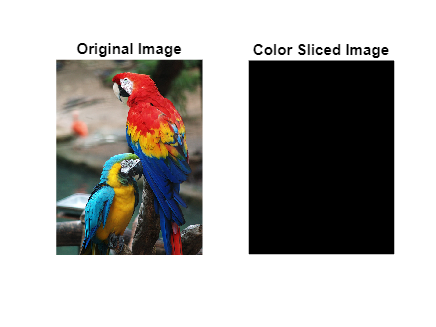

% Read the original image
originalImage = imread('loro.jpg');

% Define the prototype color and width W
a = [0, 255, 255]; % Prototype color components in RGB
W = 0.5; % Width of the cube

% Initialize the output image
slicedImage = zeros(size(originalImage));

dins_if = 0;
fora_if = 0;

% Apply the cube-based color slicing transformation to each pixel
for i = 1:size(originalImage, 1)
    for j = 1:size(originalImage, 2)
        if all(abs(double(originalImage(i, j, :)) - a) <= W/2)
            dins_if = dins_if + 1;
            slicedImage(i, j, :) = originalImage(i, j, :);
        else
            fora_if = fora_if + 1;
        end
    end
end

% Display the original image
subplot(1, 2, 1);
imshow(originalImage);
title('Original Image');

% Display the color sliced image
subplot(1, 2, 2);
imshow(uint8(slicedImage));
title('Color Sliced Image');